## **Plot of Given Function**

- Plot of Function:

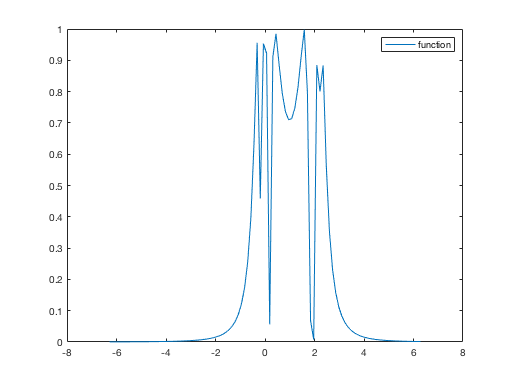

x = linspace(-2*pi,2*pi,100);
y = @(x) sin(1./(x.*(2-x))).^2;

plot(x,y(x))
legend('function')

- Plot of Forward, Backward, and Central (to the cubic approximation) Derivative:

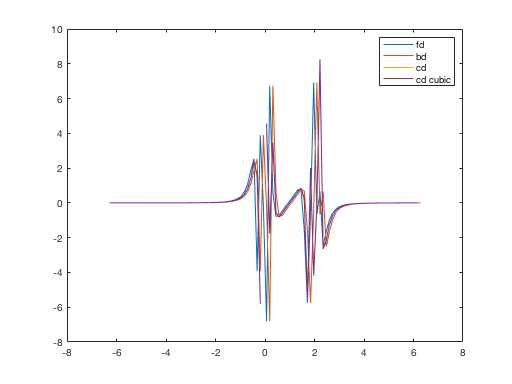

[dyf,dxf] = Der(y,x,'fd');
[dyb,dxb] = Der(y,x,'bd');
[dyc,dxc] = Der(y,x,'cd');
[dycubic,dxcubic] = Der(y,x,'cd_cubic');

plot(dxf,dyf,dxb,dyb,dxc,dyc,dxcubic,dycubic)
legend('fd','bd','cd','cd cubic','Location','northeast')

- Plot of Forward, Backward, and Central (to the cubic approximation) Second Derivative:

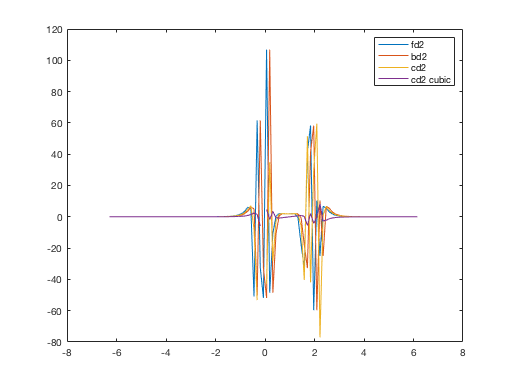

[dyf2,dxf2] = Der(dyf,dxf,'fd');
[dyb2,dxb2] = Der(dyb,dxb,'bd');
[dyc2,dxc2] = Der(dyc,dxc,'cd');
[dycubic2,dxcubic2] = Der(y,x,'cd_cubic');

plot(dxf2,dyf2,dxb2,dyb2,dxc2,dyc2,dxcubic2,dycubic2)
legend('fd2','bd2','cd2','cd2 cubic','Location','northeast')

## Plot of Given Data:

- Plot of Data:

Load .mat file and view contents- contains double arrays X and Y, each with 39 points

load derdata.mat

whos -file derdata.mat

  Name       Size            Bytes  Class     Attributes

  X         39x1               312  double              
  Y         39x1               312  double              



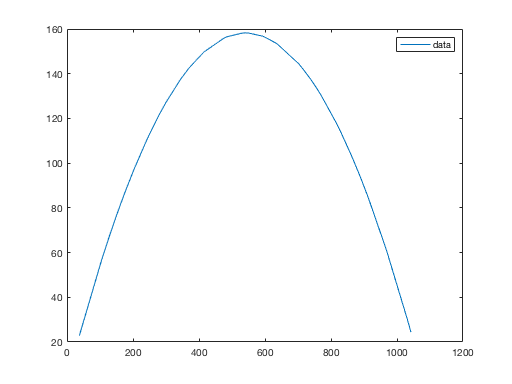


filename = 'derdata.mat';
myVars = {'X','Y'};
S = load(filename,myVars{:});

plot(S.X,S.Y)
legend('data')

- Plot of Forward, Backward, and Central (to the cubic approximation) Derivative:

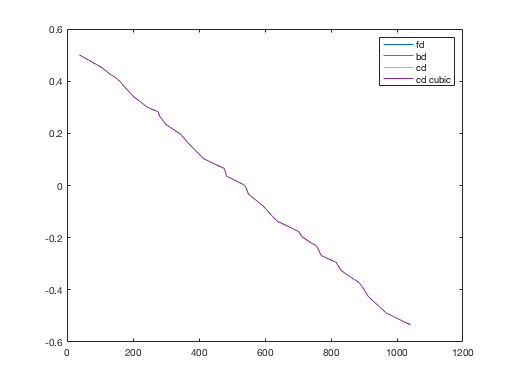

[dyf_data,dxf_data] = Der(S.Y,S.X,'fd');
[dyb_data,dxb_data] = Der(S.Y,S.X,'bd');
[dyc_data,dxc_data] = Der(S.Y,S.X,'cd');
[dycubic_data,dxcubic_data] = Der(S.Y,S.X,'cd_cubic');

plot(dxf_data,dyf_data,dxb_data,dyb_data,dxc_data,dyc_data,dxcubic_data,dycubic_data)
legend('fd','bd','cd','cd cubic','Location','northeast')

- Plot of Forward, Backward, and Central (to the cubic approximation) Second Derivative:

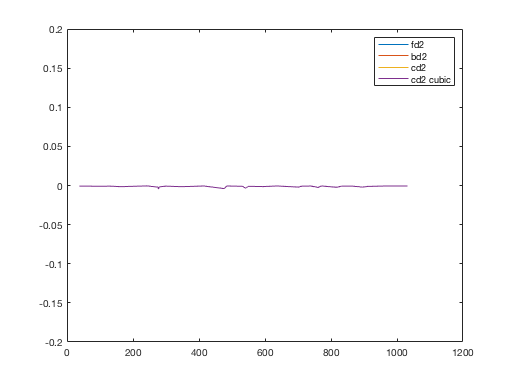

[dyf2_data,dxf2_data] = Der(dyf_data,dxf_data,'fd');
[dyb2_data,dxb2_data] = Der(dyb_data,dxb_data,'bd');
[dyc2_data,dxc2_data] = Der(dyc_data,dxc_data,'cd');
[dycubic2_data,dxcubic2_data] = Der(dycubic_data,dxcubic_data,'cd_cubic');

plot(dxf2_data,dyf2_data,dxb2_data,dyb2_data,dxc2_data,dyc2_data,dxcubic2_data,dycubic2_data)
legend('fd2','bd2','cd2','cd2 cubic','Location','northeast')
ylim([-0.2 0.2])